clear
close all

## construct the grid

Lx = 100;
Ly = 100;

Rx = 10;
Ry = 10;

x = linspace(-Rx,Rx,Lx);
y = linspace(-Ry,Ry,Ly);

[mx,my] = meshgrid(x,y);

dx = x(2)-x(1);
dy = y(2)-y(1);

## construct a 2D function

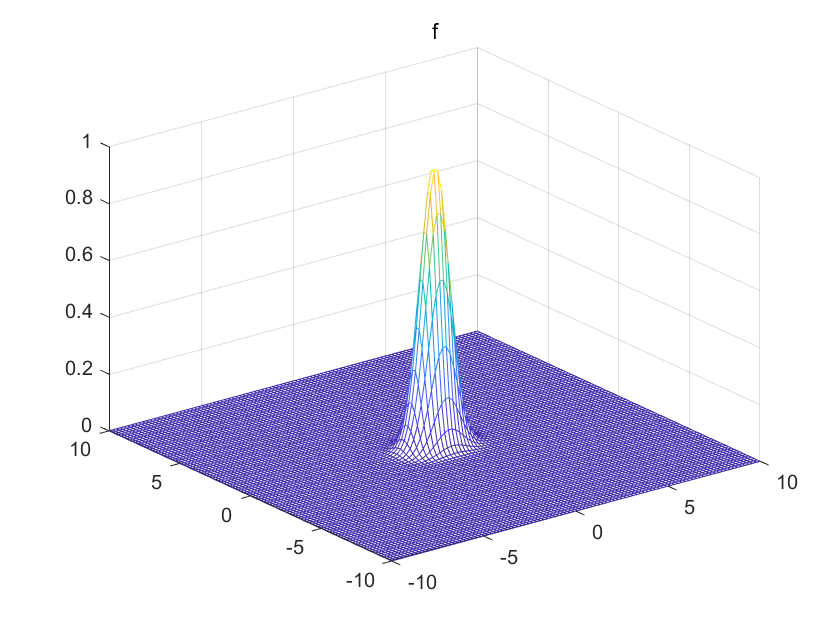

f = exp( -mx.^2 - 2*my.^2 );

figure;
mesh(mx,my,f);
title('f')

## using del2

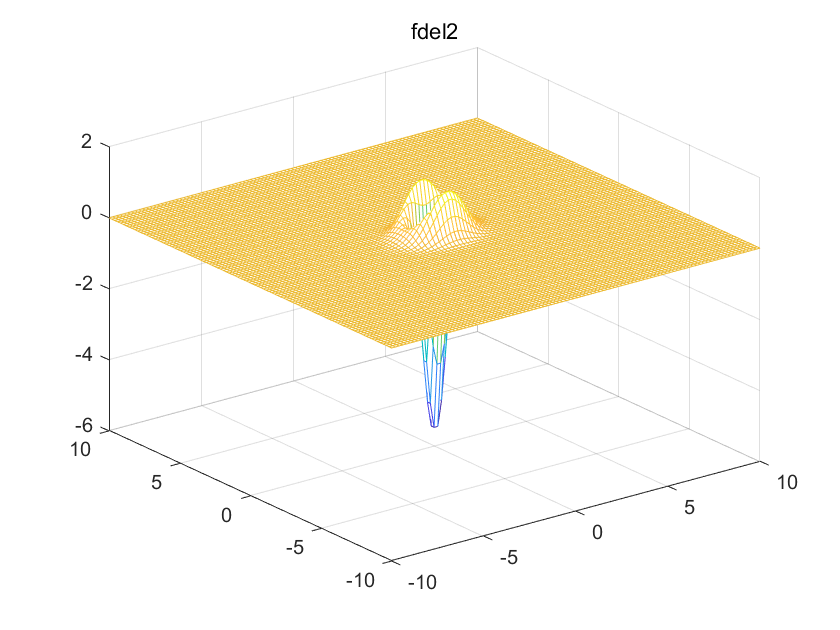

fdel2 = 4*del2(f,dx,dy);

figure;
mesh(mx,my,fdel2);
title('fdel2')

## use 5-point stencil ([https://en.wikipedia.org/wiki/Discrete_Laplace_operator](https://en.wikipedia.org/wiki/Discrete_Laplace_operator))

matrix = [0, 1, 0; 1, -4, 1; 0, 1, 0];
disp(matrix)

     0     1     0
     1    -4     1
     0     1     0



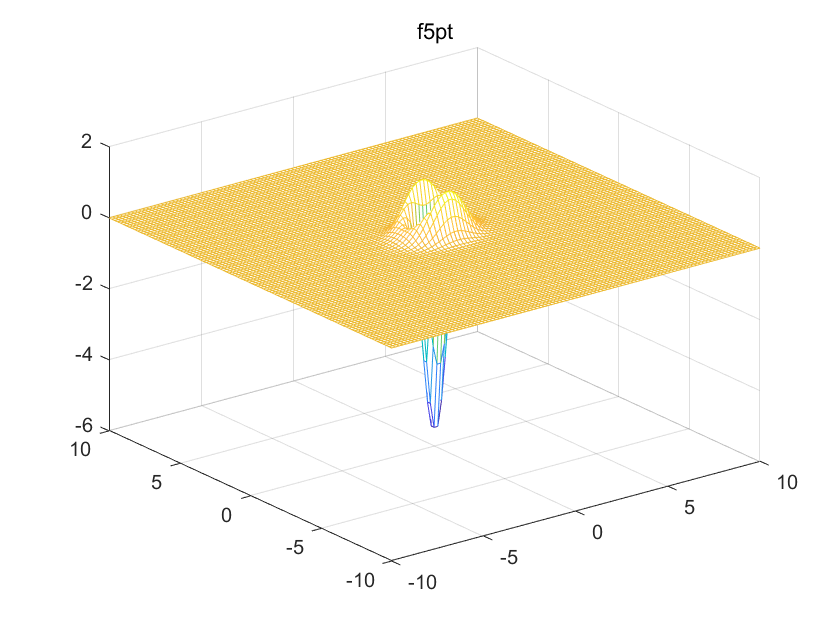


temp = conv2(f,matrix,'valid')/dx/dy;
fconv = zeros(Lx,Ly);
fconv(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,fconv);
title('f5pt')


% check the difference
diff = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff = -1.0914e-15

## use 9-point stencil ([https://en.wikipedia.org/wiki/Discrete_Laplace_operator](https://en.wikipedia.org/wiki/Discrete_Laplace_operator))

matrix = [0.25, 0.5, 0.25; 0.5, -3, 0.5; 0.25, 0.5, 0.25];
disp(matrix)

    0.2500    0.5000    0.2500
    0.5000   -3.0000    0.5000
    0.2500    0.5000    0.2500



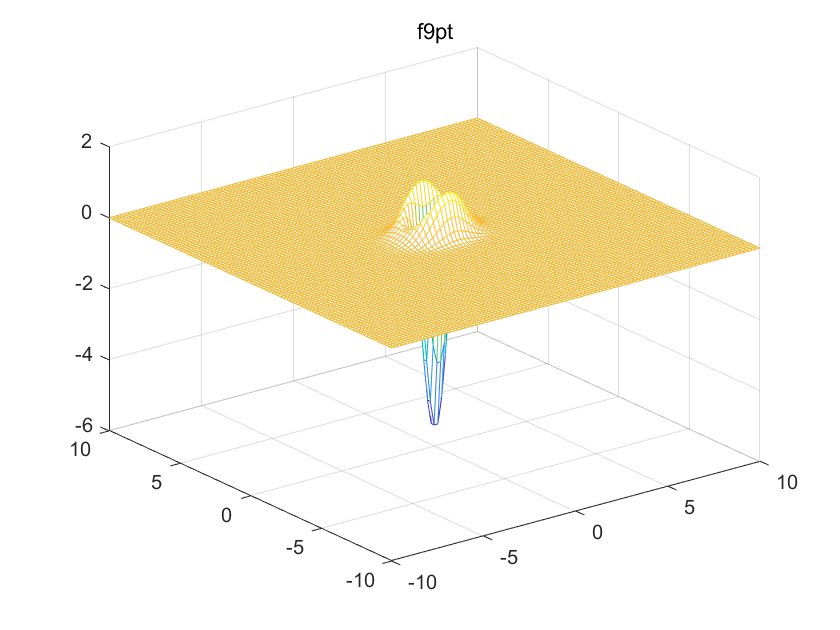


temp = conv2(f,matrix,'valid')/dx/dy;
fconv = zeros(Lx,Ly);
fconv(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,fconv);
title('f9pt')


% check the difference
diff = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff = 9.4175e-15

## use 9-point stencil 2  ([https://core.ac.uk/download/pdf/81936845.pdf](https://core.ac.uk/download/pdf/81936845.pdf))

matrix = [1, 4, 1; 4, -20, 4; 1, 4, 1];
disp(matrix)

     1     4     1
     4   -20     4
     1     4     1



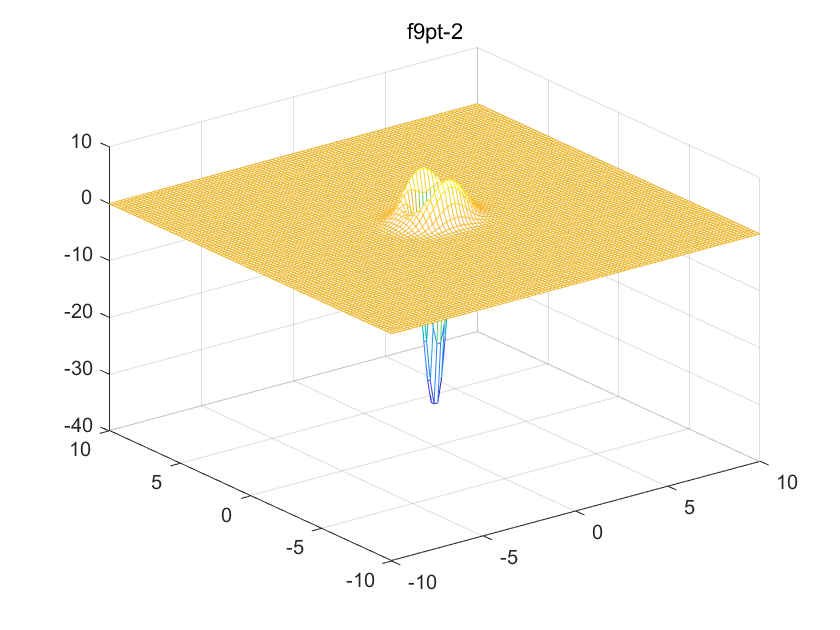


temp = conv2(f,matrix,'valid')/dx/dy;
fconv = zeros(Lx,Ly);
fconv(2:end-1,2:end-1)=temp;

figure;
mesh(mx,my,fconv);
title('f9pt-2')


% check the difference
diff = sum(sum( fdel2(2:end-1,2:end-1) - temp ))

diff = 2.0427e-13

## use 9-point stencil 3  (https://www-m2.ma.tum.de/foswiki/pub/M2/Allgemeines/NumPro2CSESS13/tutorial_08_pde_finite_diff_2_solution.pdf)

## or 1D 5-points ([https://en.wikipedia.org/w/index.php?title=Finite_difference_coefficient&oldid=930406921](https://en.wikipedia.org/w/index.php?title=Finite_difference_coefficient&oldid=930406921))

matrix = [0 0 -1/12 0 0 ; ...
    0 0 4/3 0 0 ; ...
    -1/12 4/3 -5 4/3 -1/12; ...
    0 0 4/3 0 0 ; ...
    0 0 -1/12 0 0 ];
disp(matrix)

         0         0   -0.0833         0         0
         0         0    1.3333         0         0
   -0.0833    1.3333   -5.0000    1.3333   -0.0833
         0         0    1.3333         0         0
         0         0   -0.0833         0         0



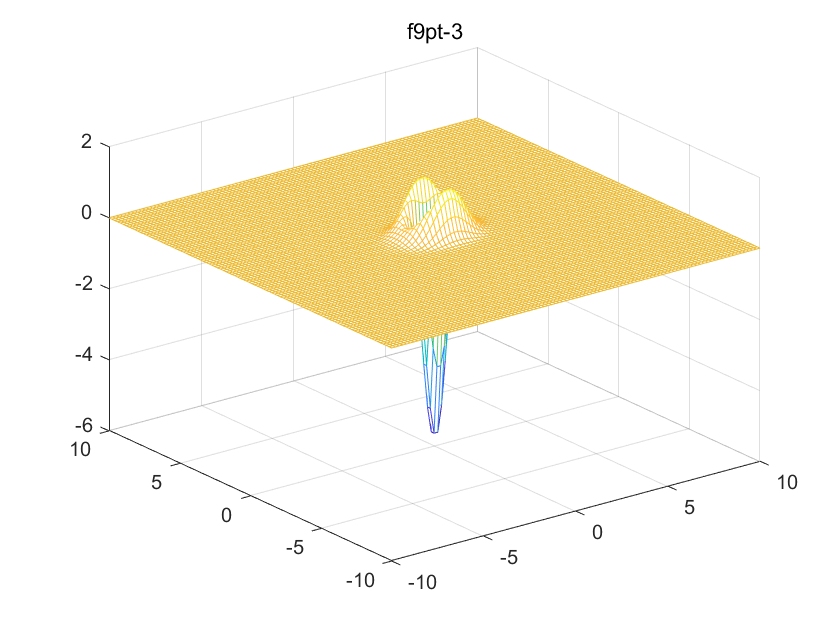


temp = conv2(f,matrix,'valid')/dx/dy;
fconv = zeros(Lx,Ly);
fconv(3:end-2,3:end-2)=temp;

figure;
mesh(mx,my,fconv);
title('f9pt-3')


% check the difference
diff = sum(sum( fdel2(3:end-2,3:end-2) - temp ))

diff = 3.2576e-13

## call fdel2_1d5pts.m

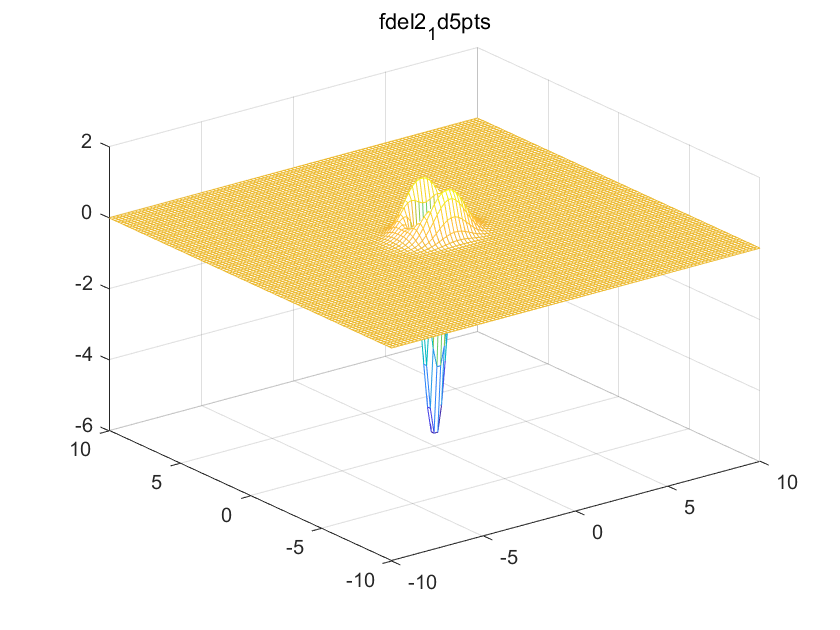

fcall = fdel2_1d5pts(f,dx);

figure;
mesh(mx,my,fcall);
title('fdel2_1d5pts')


% check the difference
diff = sum(sum( fdel2(3:end-2,3:end-2) - fcall(3:end-2,3:end-2) ))

diff = 3.2576e-13

## use 1D 7-points ([https://en.wikipedia.org/w/index.php?title=Finite_difference_coefficient&oldid=930406921](https://en.wikipedia.org/w/index.php?title=Finite_difference_coefficient&oldid=930406921))

% construct the matrix
matrix = zeros(7,7);

mid = 4;

array = [1/90	-3/20	3/2	-49/18	3/2	-3/20	1/90];
matrix(:,mid) = array;
matrix(mid,:) = array;
matrix(mid,mid) = 2*(-49/18);

disp(matrix)

         0         0         0    0.0111         0         0         0
         0         0         0   -0.1500         0         0         0
         0         0         0    1.5000         0         0         0
    0.0111   -0.1500    1.5000   -5.4444    1.5000   -0.1500    0.0111
         0         0         0    1.5000         0         0         0
         0         0         0   -0.1500         0         0         0
         0         0         0    0.0111         0         0         0



sum(sum(matrix))

ans = -4.8746e-16

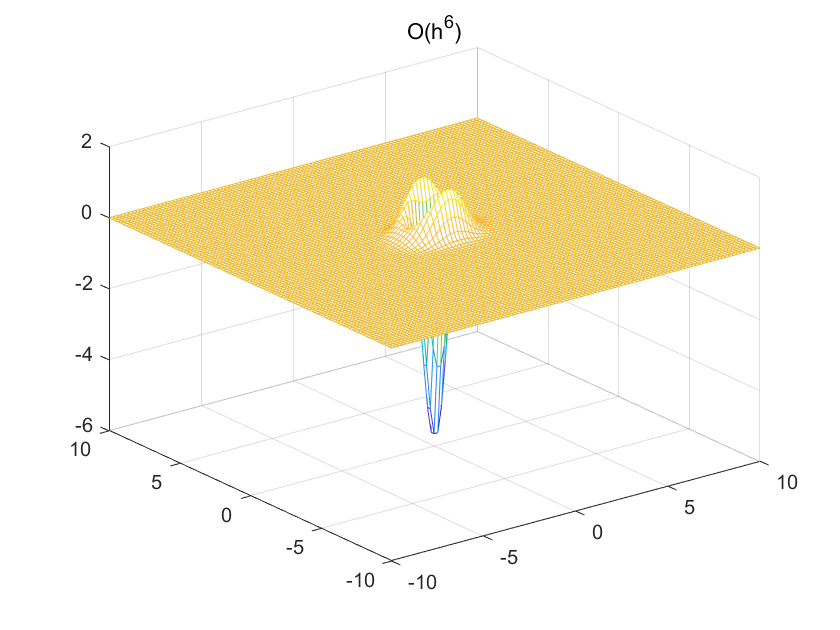


% calcualtion
temp = conv2(f,matrix,'valid')/dx/dy;
fconv = zeros(Lx,Ly);
fconv(4:end-3,4:end-3)=temp;

figure;
mesh(mx,my,fconv);
title('O(h^6)')


% check the difference
diff = sum(sum( fdel2(4:end-3,4:end-3) - temp ))

diff = 2.6553e-13

## call fdel2_1d7pts.m

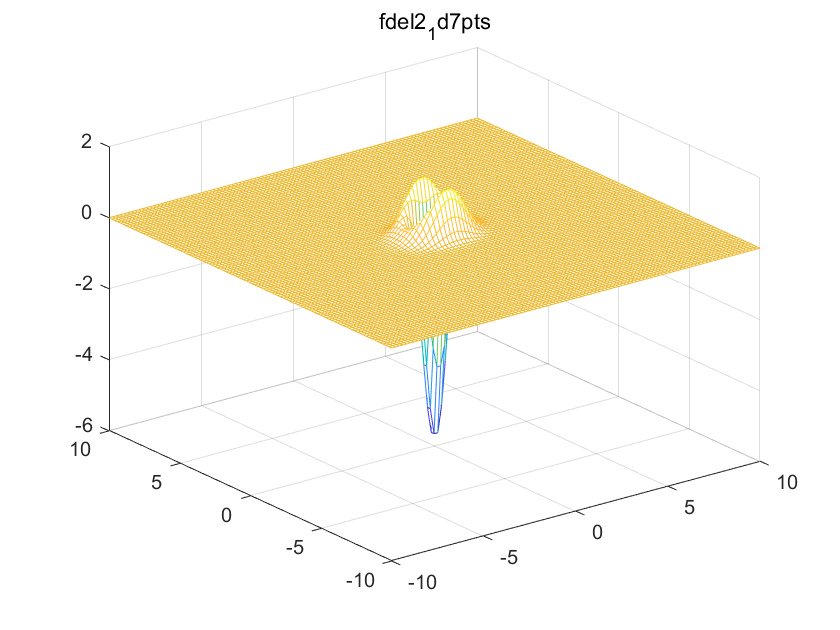

fcall = fdel2_1d7pts(f,dx);

figure;
mesh(mx,my,fcall);
title('fdel2_1d7pts')


% check the difference
diff = sum(sum( fdel2(4:end-3,4:end-3) - fcall(4:end-3,4:end-3) ))

diff = 2.6553e-13